addpath functions/SETUP/
addpath functions/ACT/
addpath functions/SENSE/

clear all
clc

robotPi = SETUP_pi("192.168.16.66");
neo = SETUP_gps(robotPi);


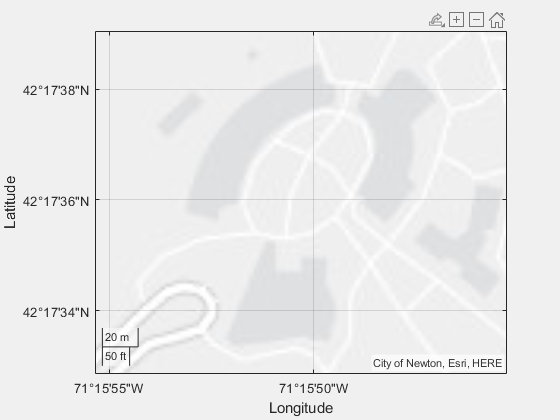

% Create a stand alone figure to plot GPS rover position data in
gpsRoverPlot=figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])

% Plot out a trail line bewteen two waypoints just o demo line drawing
%geoplot(waypoints(:,2),waypoints(:,1),'y-','DisplayName','Rover GPS Track')

while 1
    [X,Y,heading] = SENSE_gps(neo);
    % plot rover poition, you can change this line to plot roverX and RoverY 
    %geo plot(latt, long)
    geoplot(Y, X, 'g*','DisplayName','Rover Position')
    geolimits([42.29246 42.29418],[-71.26537 -71.26258])
    text(Y,X,{sprintf('Long: %d', X),sprintf('Latt: %d', Y)},'Color','w')
    % Import a satellite photo basemap to draw on
    geobasemap satellite
    legend('Location','southeast')
    movegui(gpsRoverPlot,'south');
    title('Planetary Rover Position')
    pause(1)
end

ans = 1×2 uint8 row vector
    40   198


ans = 1×2 uint8 row vector
    5   32


ans = 1×2 uint8 row vector
    32   128


ans = 1×2 uint8 row vector
    12   181
